# Lab 9 – Frequency Spectrum 

# EE252L/251L: Signals and Systems Lab

## Dr. Basit Memon and Ms. Hira Mustafa

## Name: M. Shees Abbas                                           ID: ma11212

## Task 1:

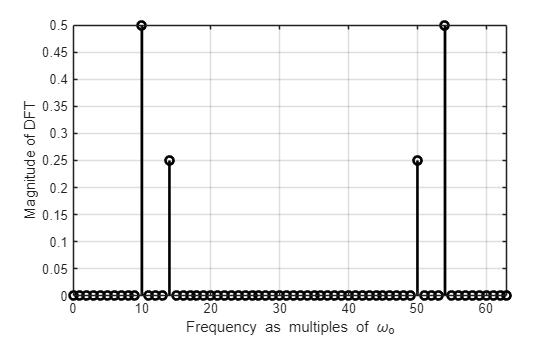

P = 64;
w = 2*pi/P;
n = 0:P-1;
x = cos(10*w*n) + 0.5*cos(14*w*n); %Finite-time signal
hx = fft(x); %Compute the DFT of x
stem(n,abs(hx)/P,'k','LineWidth',2); %Compute and plot magnitude of coefficients
ylabel('Magnitude of DFT');
xlabel('Frequency as multiples of \omega_o');
axis([0 P-1 0 inf]);
grid;

## Task 2:

### **(a)**

clc; clear; close all;
fs = 8000;
n = 1000;
t = (0:n-1)/fs;
w1 = 400;
x1 = sin(2*pi*w1*t);

### (b)

hx1 = fft(x1,n);
hx1_shifted = fftshift(hx1);

### **(c)**

fhz = (-n/2:(n/2)-1)*(fs/n);

### (d)

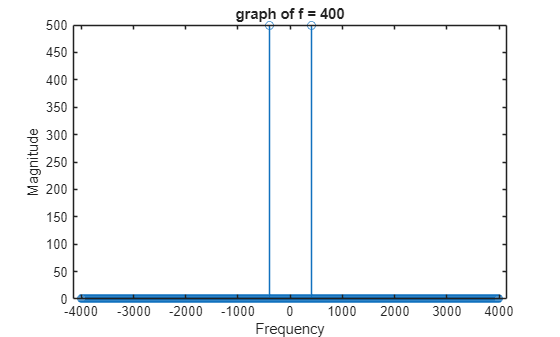

figure;
stem(fhz, abs(hx1_shifted))
title('graph of f = 400')
ylabel('Magnitude');
xlabel('Frequency');

### (e)

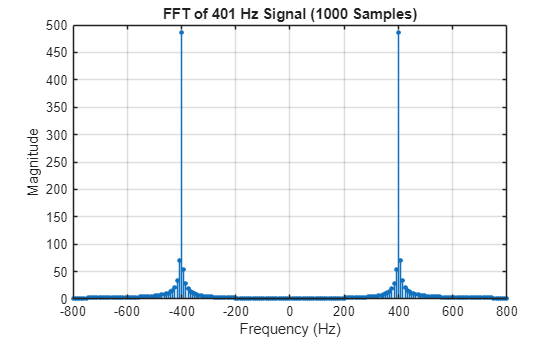

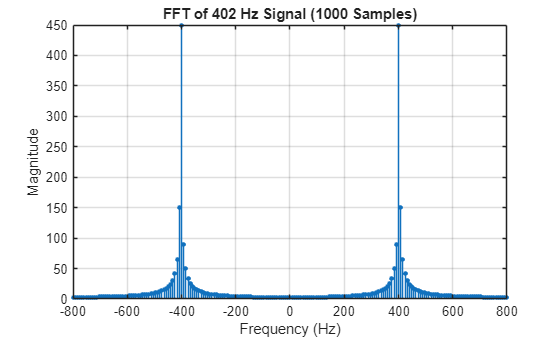

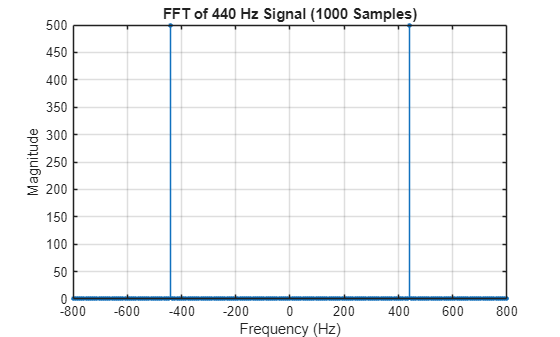

frequencies = [401, 402, 440];
for i = 1:length(frequencies)
    f = frequencies(i);
    x = sin(2 * pi * f * t);
    hx = fftshift(fft(x, n));
    
    figure;
    stem(fhz, abs(hx), 'filled', 'MarkerSize', 3);
    title(['FFT of ', num2str(f), ' Hz Signal (1000 Samples)']);
    xlabel('Frequency (Hz)');
    ylabel('Magnitude');
    grid on;
    xlim([-800 800]);
end

**400 Hz and 440 Hz** both frequencies result in an **integer number of complete cycles** over the 1000-sample window, the waveform starts and ends at the exact same phase point seamlessly. There are no sudden truncation jumps at the edges of the 1000-sample block.

In contrast, a frequency like **401 Hz** yields 50.125 cycles. The window cuts the sine wave mid-cycle, causing a harsh discontinuity between the start and end of the data block. This sharp edge creates **spectral leakage**, spreading the energy into neighboring frequency bins.

### (f)

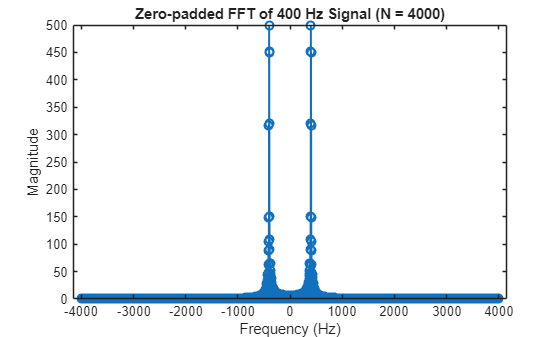

fs = 8000;
n_samples = 1000;
t = (0:n_samples-1)/fs;
w1 = 400;
x1 = sin(2*pi*w1*t);

N = 4000;
hx2 = fft(x1, N);
hx2_shifted = fftshift(hx2);
fhz = (-N/2 : (N/2)-1) * (fs / N);

figure;
stem(fhz, abs(hx2_shifted), 'LineWidth', 1.5);
title('Zero-padded FFT of 400 Hz Signal (N = 4000)');
xlabel('Frequency (Hz)');
ylabel('Magnitude');

The graph will change from discrete stems into a **smooth, continuous curve**. Because zero-padding interpolates the frequency bins, it fills in the gaps between the original points to outline the shape of the spectral leakage envelope, making the overall curve look continuous.

### (g)

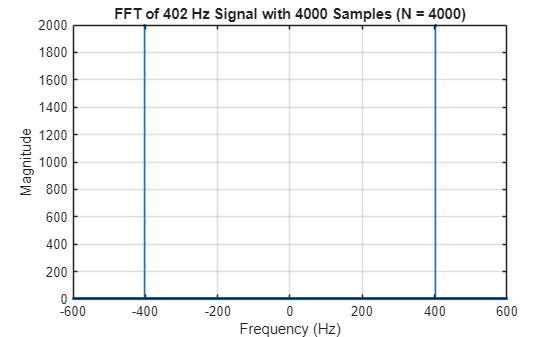

n_long = 4000;
t_long = (0:n_long-1)/fs;
w_402 = 402;
x_402_long = sin(2*pi*w_402*t_long);

hx_402_long = fft(x_402_long, n_long);
hx_402_long_shifted = fftshift(hx_402_long);
fhz_long = (-n_long/2 : (n_long/2)-1) * (fs / n_long);

figure;
stem(fhz_long, abs(hx_402_long_shifted), 'filled', 'MarkerSize', 2);
title('FFT of 402 Hz Signal with 4000 Samples (N = 4000)');
xlabel('Frequency (Hz)');
ylabel('Magnitude');
grid on;
xlim([-600 600]);

The graph will display a **much taller, sharper, and narrower peak** at 402 Hz. The messy, widespread "side lobes" (spectral leakage) from the 1000-sample version will disappear, leaving a clean, isolated single-frequency spike.

## Task 3

### (a)

fs = 8000;
N = 8000;
t = (0:N-1) / fs;
x = chirp(t,0,1,4000);

### (b)

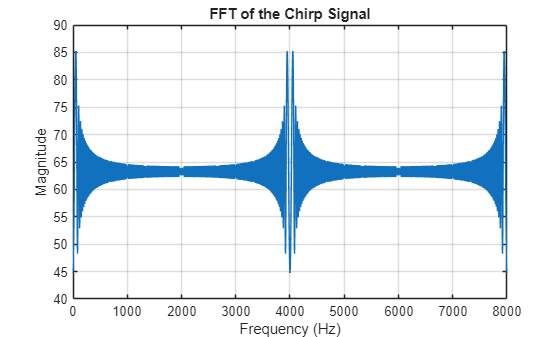

X = fft(x);
f_axis = (0:N-1) * (fs / N);

figure;
plot(f_axis, abs(X));
title('FFT of the Chirp Signal');
xlabel('Frequency (Hz)');
ylabel('Magnitude');
grid on;

### (c)

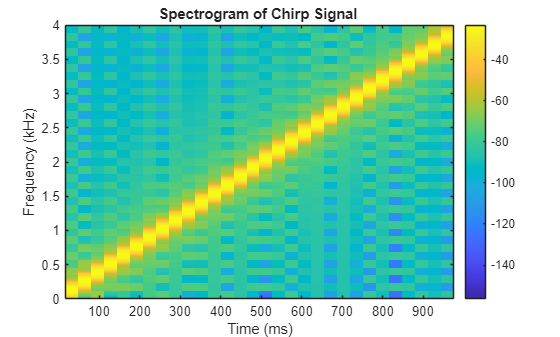

figure;
spectrogram(x, 512, [], 1024, fs, 'yaxis');
title('Spectrogram of Chirp Signal ');
colorbar;

the resulting spectrogram displays a clear diagonal line sloping upwards from **0th sample** to **8000 sample**, which perfectly agrees with our understanding and theoretical derivation of the signal's time-varying frequency. Over the 1-second duration, the frequency increases linearly

### (d)

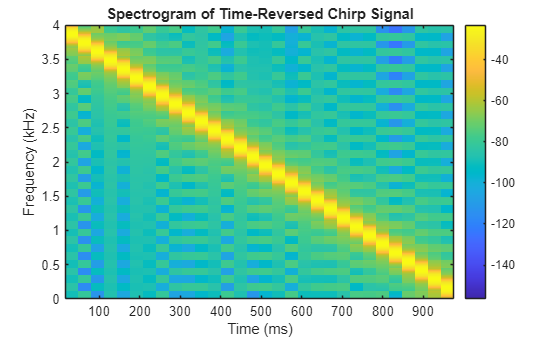

x_rev = x(8000:-1:1);

figure;
spectrogram(x_rev, 512, [], 1024, fs, 'yaxis');
title('Spectrogram of Time-Reversed Chirp Signal');
colorbar;

This makes complete sense because time-reversing the signal (x(-t)) reverses the order in which the frequency components are presented. Instead of starting at **0th sample** and sweeping up to **8000th sample**, the reversed signal starts at **8000th sample** and sweeps downwards to **0th sample**, which is represented on the spectrogram by a diagonal line sloping downwards from left to right